clc;
clear;
close all;

%% DEFINITION OF SYSTEM

%Number of agents
m = 2;
%Number of state variables
n = 2;
%Overall dimension of the system         
v = m*n;

%Number of state variables seen by each observer
numberOfOnes_C = int8(n/4);
%Maximum number of connections in the graph for each observer
numberOfOnes_E = int8(m/2);

% Get a list of random locations, with no number repeating.
for i = 1:m
    indexes_C = randperm(n);
    indexes_E = randperm(m);
    
    % Start off with all zeros.
    c = zeros(1, n);
    e = zeros(1, m);
    
    % Now make half of them, in random locations, a 1.
    c(indexes_C(1:numberOfOnes_C)) = 1;
    e(indexes_E(1:numberOfOnes_E)) = 1;
    
    %Output Matrix
    C(i,:) = c;
    
    E(i,:) = e; % ones(1,m);                    
    E(i,i) = 0;
end

%State Matrices
%A = randi([-10, 10], n)
A = [0 -1; 1 0]

A =      0    -1
     1     0


C = [ 1 0; 0 1]

C =      1     0
     0     1


E = [-1  1; 1  -1]     

E =     -1     1
     1    -1



%Check the Jointly Observability
O = obsv(A,C);

if n == rank(O) 
    disp("System is Jointly Observable")
else
    disp("System is not Jointly Observable")
end 

System is Jointly Observable


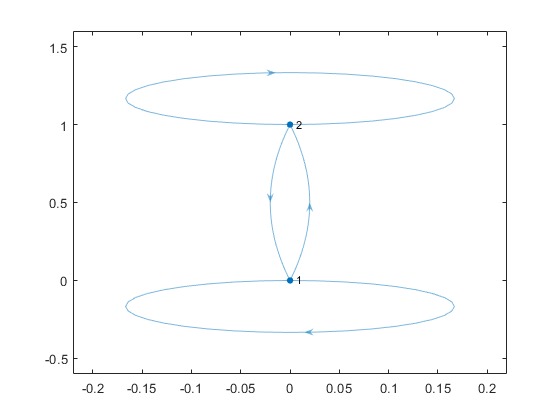


%Check the strongly connected components
GraphE = digraph(E);
plot(GraphE)

s = conncomp(GraphE);

if s == ones(1,m)
    disp("Graph is strongly connected")
else
    disp("Graph is weakly connected")
end

Graph is strongly connected




%% DEFINITION OF MATRICES FOR OBSERVERS

%Kronecker product for matrix A
Abig = kron(eye(m),A);

%The transpose of incidence matrix of communication graph 
Ebig = E';         
Ebig =  kron(Ebig, eye(n));

%Matrices defined by unit vector in position k
Bbig = kron(eye(n), eye(m));

%state feedback controller gain matrix
poles = -2*ones(1,n); %desired poles
Kgain = place(A',eye(n),poles)

Kgain =      2     1
    -1     2


Kgain = 0*eye(n);

F = 1*eye(n*m);
K = kron(eye(m), diag(Kgain));

Kbig = [K -F];

%Definition of C_
for i = 1:m
    
    zeroVectorForward = zeros(1,n*(m-i));
    zeroVectorBackward = zeros(1,n*(i-1));
    if( i > 1 ) 
        Cbig(i,:) = [zeroVectorBackward C(i,1:n) zeroVectorForward];
    elseif (i == 1)
        Cbig(i,:) = [C(i,1:n) zeroVectorForward];
    elseif (i == m)
        Cbig(i,:) = [zeroVectorBackward C(i,1:n)]; 
    end
end

Cbig = [Cbig ; Ebig];

H = Abig -Kbig*Cbig

H =     -1    -1     1     0
     1    -1     0     1
     1     0    -1    -1
     0     1     1    -1


System (Cbig, H, Bbig) is Observable and Controllable


The minimal polynomial is equal to the characteristic polynomial


System (H, Cdyn) is Observable


alpha =      1     4     6     4     5


ans = 5

Desired polynomial coefficients:\n


     1    10    40    80    80    32



ans =   -2.0020 + 0.0015i
  -2.0020 - 0.0015i
  -1.9992 + 0.0024i
  -1.9992 - 0.0024i
  -1.9975 + 0.0000i


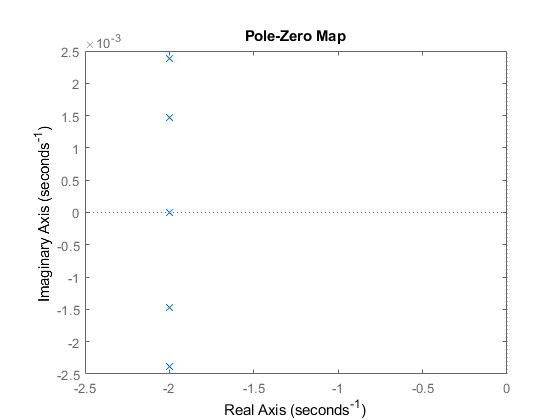

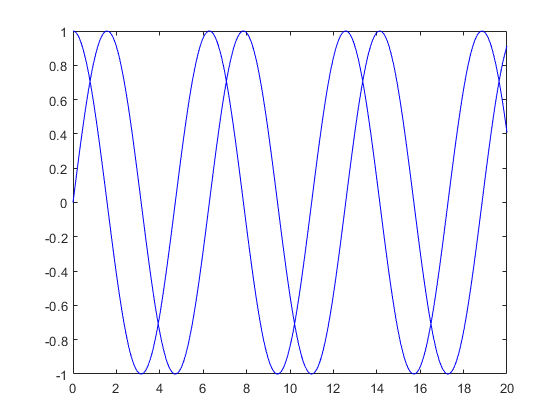

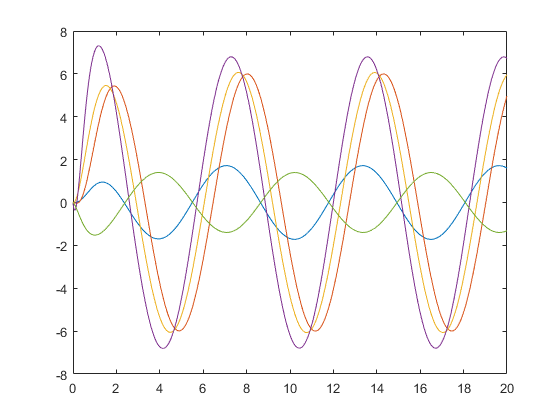

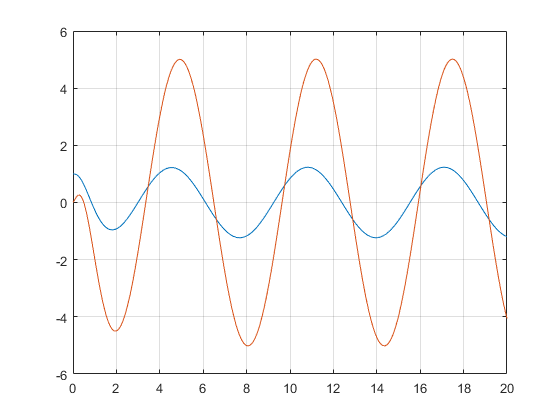






%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


sys = ss(H,Bbig(1:v,3:v),Cbig(2,1:v),zeros(1,n));
%pzmap(sys)

%%Observability and Controllability of the total system
Obar = obsv(H,Cbig(1:n,1:v));
Rbar = ctrb(H,Bbig(1:v,1:n));

if v == rank(Obar) && v == rank(Rbar)
    disp("System (Cbig, H, Bbig) is Observable and Controllable")
    
    
    % Dynamic Compensator of dimension l implemented to the last observer
    l = m-1;
    
    Bdyn = Bbig(1:v,3:v);
    
    % Vector g' used to obtain the matrix phi 
    Cdyn = C(m,1:n)*Bdyn';
    
    % System A,B,C (Dynamic) put in the companion form
    csys_dyn = ss(H,Bdyn,Cdyn,zeros(1,2));
    %csys_dyn = canon(csys_dyn,'companion');
    
    if charpoly(csys_dyn.A) == minpoly(csys_dyn.A)
        disp('The minimal polynomial is equal to the characteristic polynomial')
    end
    
    % Check the observability by the vector g' (Cdyn)
    Odyn = obsv(csys_dyn.A,csys_dyn.C);
    
    if v == rank(Odyn)
        
        disp("System (H, Cdyn) is Observable")
        
        % Characteristic polynomial of H
        alpha = charpoly(csys_dyn.A)
        
        % Matrices L and phi creation
        L = zeros(v+l,l+1);
        
        for i= 1:(v+l)
         
            if(i == 1)
                L(i,1:n) =  csys_dyn.C*csys_dyn.B;
            else
                for j = 1:i
                    
                    if j == 1
                        L(i,1:n) = csys_dyn.C*(csys_dyn.A^(i-1))*csys_dyn.B;
                    else
                        L(i,1:n) = L(i,1:n) + alpha(j)*csys_dyn.C*(csys_dyn.A^(i-j))*csys_dyn.B;
                    end
                end
            end
        end  
  
        phi = [1 alpha(2:v+1);  
               zeros(2,1) L(1:v,:)';
               L(1:v+l,:)']';
        
        rank(phi)
        
        %desired coefficients
        beta = charpoly(-2*eye(v+l));
        disp('Desired polynomial coefficients:\n');
        disp(beta)

        gamma = beta(1,2:v+1) - alpha(1,2:v+1);
        gamma = [gamma beta(1,6)];
        
        X = linsolve(phi,gamma');
        
        Bdyn = [csys_dyn.B zeros(v,l); zeros(l,n) eye(l)];
        Cdyn = [csys_dyn.C zeros(1,l); zeros(l,v) eye(l)];
        Kdyn = [-X(4)  -X(2)+X(4)*X(1);
                -X(5)  -X(3)+X(5)*X(1);
                 1            -X(1)];
        Ktr = Bdyn*Kdyn;
        Abar = Kdyn(3,2);
        Bbar = Kdyn(3,1);
        Cbar = Ktr(1:4,2);
        Dbar = Ktr(1:4,1);
       
        Hdyn = [csys_dyn.A+Dbar*csys_dyn.C Cbar;  Bbar*csys_dyn.C Abar];
          
        eig(Hdyn)   
        
        B_obs = [Dbar' -Bbar; Dbar' -Bbar]'; %C(1,:) 
        sys_dyn = ss(Hdyn,B_obs,eye(v+l),zeros(v+l,2));
        pzmap(sys_dyn)
             
        T = 20;
        dt = 0.01;
        t = 0:dt:T; 
        
        plant = ss(A,zeros(2,1),eye(2),zeros(2,1));
        u = 1*t;
        x0 = [1;0];
        x = lsim(plant,u,t,x0);
        y1 = C(1,:)*x';
        y2 = C(2,:)*x';
        y = C*x';        
        
        z = lsim(sys_dyn, C,t,zeros(5,1));
      
        error = x - z(:,1:2);
       figure
       plot(t,x,'b')
       
       figure
       plot(t,z(:,1:2))
       hold on 
       plot(t,z(:,3:4))
       plot(t,z(:,5))
       figure
       plot(t, error)
       grid on
    else
         disp("System (H, Cdyn) is not Observable")
    end
            
    
elseif  v == rank(Obar) && v ~= rank(Rbar)
    disp("System (Ebig, H, Bbig) is Observable and not Controllable")
elseif  v == rank(Rbar) && v ~= rank(Obar)
    disp("System (Ebig, H, Bbig) is Controllable and not Observable")
else
    disp("System (Ebig, H, Bbig) is nor Controllable neither Observable")
end


% 
%     T = 50;
%     dt = 0.01;
%     t = 0:dt:T; 
%     
%     plant = ss(A,zeros(2,1),eye(2),zeros(2,1));
%     u = 0*t;
%     x0 = [1;0];
%     x = lsim(plant,u,t,x0);
%     y1 = C(1,:)*x';
%     y2 = C(2,:)*x';
%     
%     H11 = H(1:n,1:n);
%     H12 = H(1:n,n+1:v);
%     H21 = H(n+1:2*n,1:n);
%     barH22 = Hdyn(n+1:2*n,n+1:2*n); 
%     barC = Hdyn(n+1:2*n,2*n+1);
%     barA = Hdyn(2*n+1,2*n+1);
%     barB = Hdyn(2*n+1,n+1:2*n);
%            
%     AN = [H11 H12 zeros(2,1)
%           H21 barH22 barC
%           zeros(1,2) barB barA];
%       
%     K1 = Kgain
%     K2 = Kgain
%     barD = Bdyn*Kdyn*Cdyn;
%     barD = barD(n+1:2*n,n+1:2*n)
%     
%     BN = [K1
%           barD
%           barB]; 
%       
%     plantz = ss(Hdyn,BN,eye(5),zeros(5,2));     
%    z = lsim(plantz,[y1; y2;],t,zeros(5,1));
%   
%    figure
%    plot(t,x,'b')
%    hold on 
%    plot(t,z(:,1:2),'r')
%    plot(t,z(:,3:4),'g')
%    plot(t,z(:,5),'k')
   
   
   